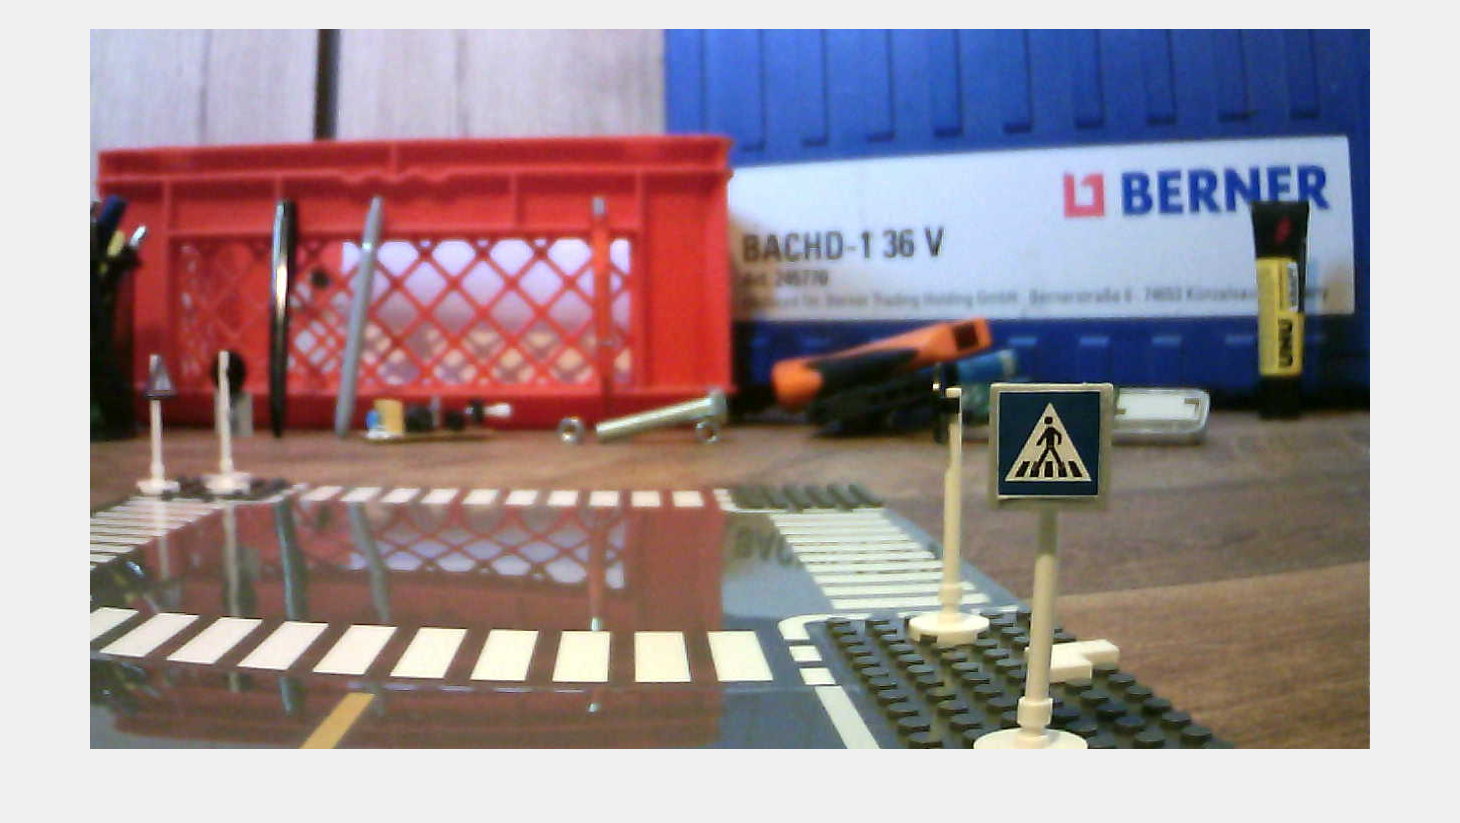

directory = "C:\Users\nicoh\OneDrive\Desktop\Matlabcode_Teamprojekt\Bilder\3 Rechteckige Schilder\Fussgaengerueberweg\Indoor_Kreuzung";
cd(directory);      % Arbeitsverzeichnis setzen

I = imread("Fussgaengerueberweg-2025-06-19__18.jpg");
imshow(I);

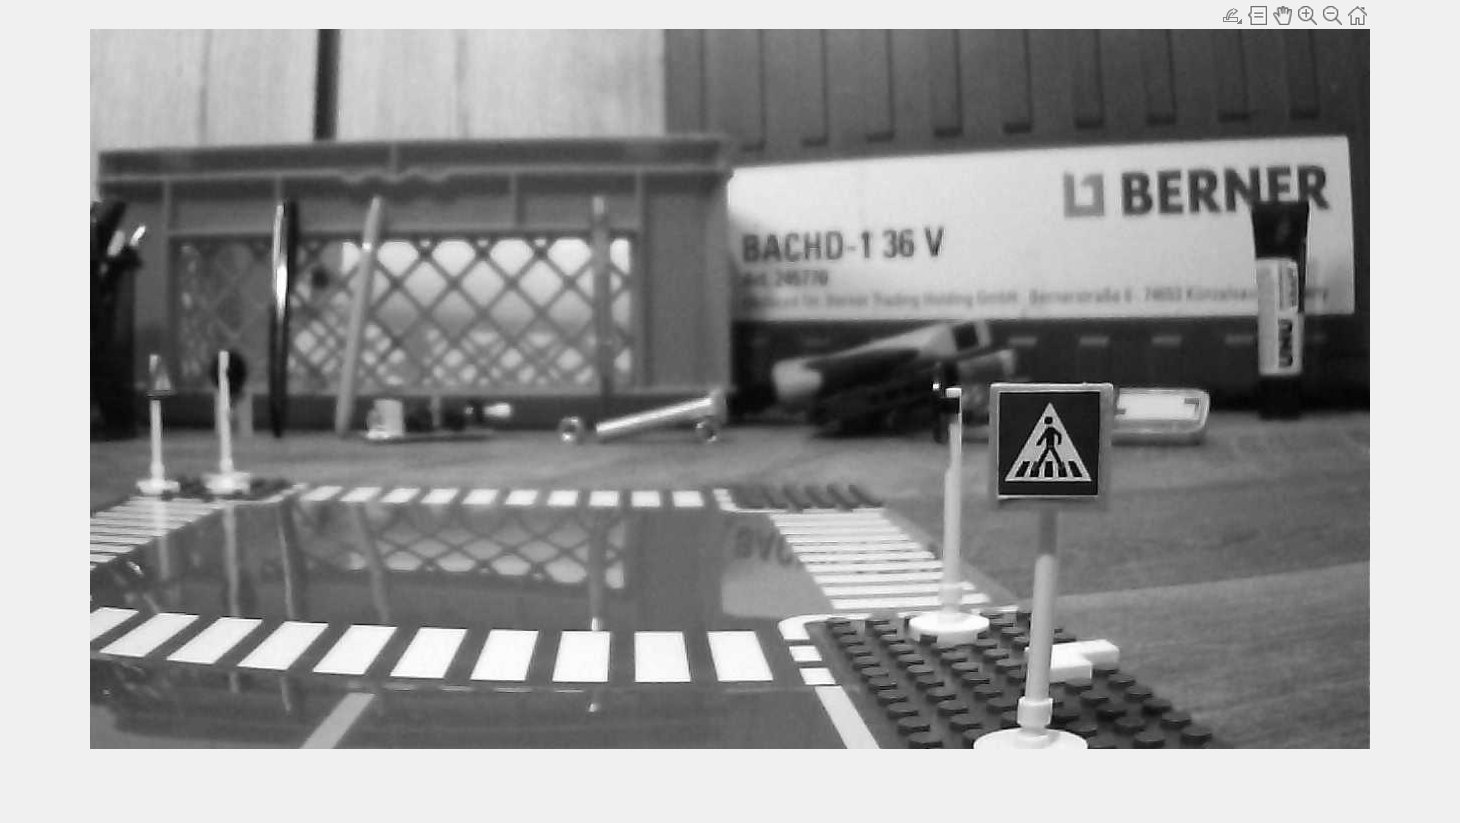

grayImage = rgb2gray(I);
imshow(grayImage);

[x, y, val] = impixel;

disp(['Grauwert an (', num2str(x), ',', num2str(y), '): ', num2str(val)]);

Grauwert an (916,369): 34  34  34


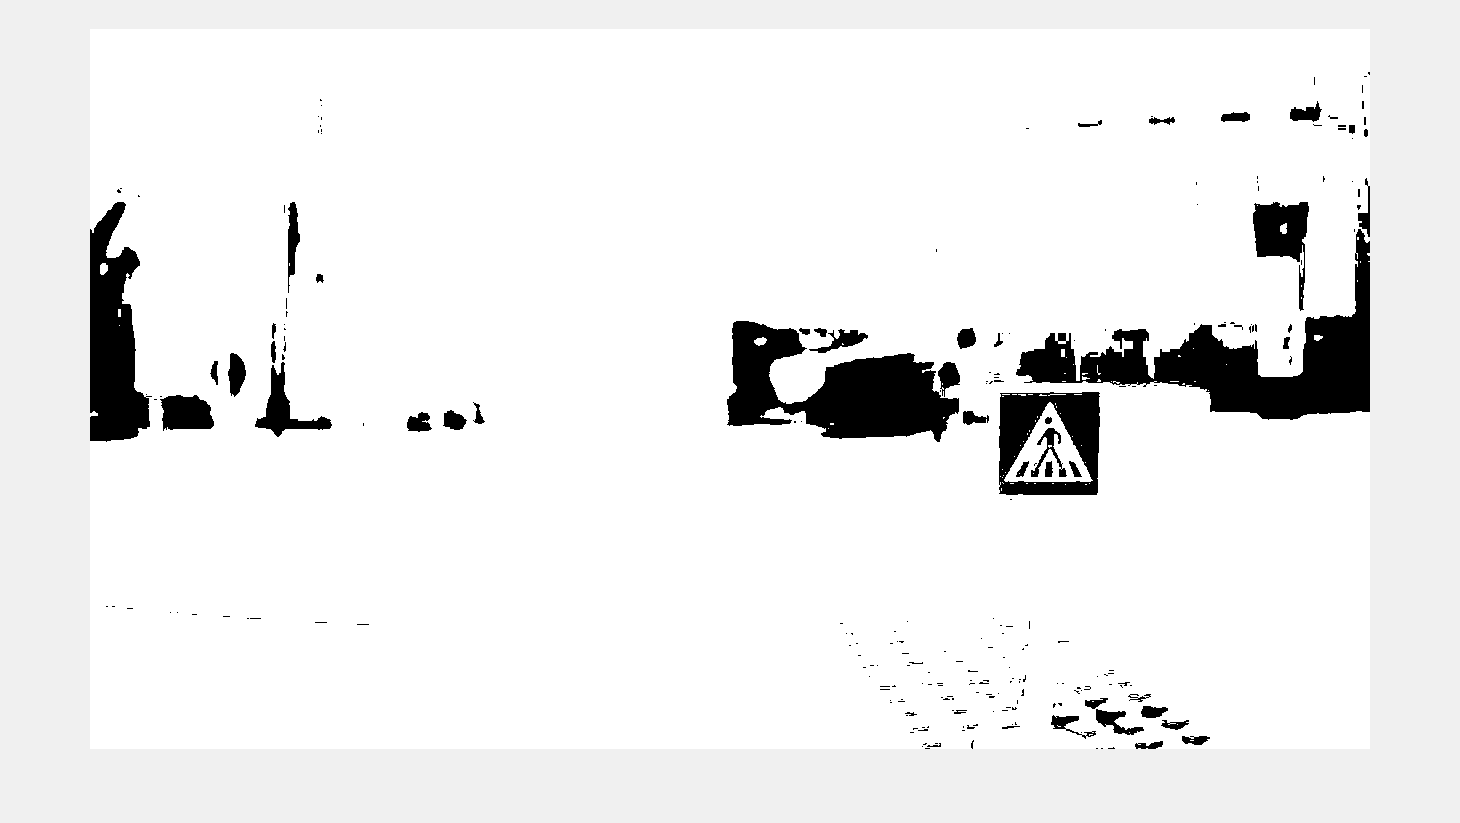


% Schwellwert in Grauwerten (0–255)
% T = val(1);aus klick übernehmen
T=40;
BW = grayImage > T;
imshow(BW);

figure; 
% eintragen der Bilddatei in excel
% writematrix(string(Pfadschild), filename, 'WriteMode', 'append');
[centers, radii] = imfindcircles(BW, [20, 200], 'ObjectPolarity','bright','Sensitivity', 0.92 )

centers = 1.0e+03 *

    0.7076    0.3458
    1.2393    0.2626
    1.1932    0.3262
    0.2176    0.3583
    0.6904    0.2724
    1.2236    0.4119
    0.9702    0.3390
    0.0646    0.2605
    0.9579    0.4378
    0.1553    0.3418


radii =    28.5225
   26.2485
   24.2080
   24.9102
   28.3272
   26.3557
   25.2977
   29.5012
   28.6951
   29.6617


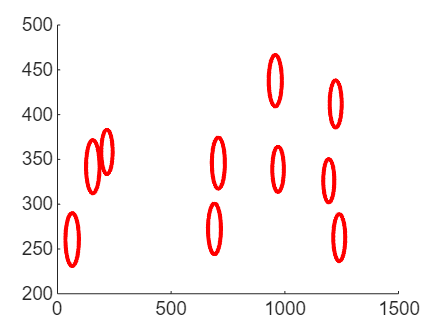

viscircles(centers, radii,'EdgeColor','r');